addpath('Classes')
addpath('Simulink Models')
addpath('Functions')

%Make sure symprefs are set correctly for this script
sympref('MatrixWithSquareBrackets',true);
sympref('AbbreviateOutput', false);
sympref('FloatingPoint',true);
sympref('TypesetOutput',true);

# Numerically Finding a Nonlinear Angular Setpoint

%Create a variable definitions object if one does not already exist. 
if (~exist('VDefs', 'var')) 

    VDefs = Var_Defs;  %Create an object of the class Var_Defs

end 

%Create a u-joint Kinematics object if one does not already exist. 
if (~exist('UJ_Knmtcs', 'var')) 

    UJ_Knmtcs = UJ_Knmtcs(VDefs); %Create an object of the class UJ_Knmtcs
    UJ_Knmtcs.derive_all; %Run all of its derivation functions

end 

%Create a ball-plate kinematics object if one does not already exist. 
if (~exist('BP_Knmtcs', 'var')) 

    BP_Knmtcs = BP_Knmtcs(VDefs, UJ_Knmtcs); %Create an object of the class BP_Knmtcs
    BP_Knmtcs.Derive_Both; %Derive all the kinematic equations for the ball-plate system
end 

%Create a ball-plate kinetics object if one does not already exist. 
if (~exist('BP_Kinetics', 'var')) 

    BP_Kinetics = BP_Kinetics(VDefs, UJ_Knmtcs, BP_Knmtcs); %Create an object of the class BP_Kinetics
    BP_Kinetics.Derive_NL_EOMs; %Derive the nonlinear equations of motion for the ball-plate system
    BP_Kinetics.Num_Params_n_Assumptions; %Input numerical parameters and assumptions
end 

%Create a linearized EOMs object if one does not already exist. 
if (~exist('Lnrzed_EOMs', 'var')) 

    Lnrzed_EOMs = Lnrzed_EOMs(VDefs, BP_Kinetics); %Create an object of the class Lnrzed_EOMs
    Lnrzed_EOMs.Derive_8th_Ordr_Lin_Sys;
    Lnrzed_EOMs.Derive_4th_Ordr_Lin_Sys;
end 

%Create a nonlinear decoupled EOMs object if one does not already exist. 
if (~exist('NL_Dcpld_EOMs', 'var')) 

    NL_Dcpld_EOMs = NL_Dcpld_EOMs(VDefs, BP_Kinetics); %Create an object of the class NL_Dcpld_EOMs
    NL_Dcpld_EOMs.Num_Params
end


## Eliminate the Input from the Nonlinear Decoupled EOMs for System 1

beta_ddot_eqn = isolate(0 == eliminate(NL_Dcpld_EOMs.NumDcpldEOMs([2 4]),VDefs.T_beta),VDefs.beta_ddot)

$$beta\_ddot\_eqn = \ddot{\beta }=75.5778\,\sin\left(\beta \right)-10.7858\,\ddot{x}+7.7042\,{\dot{\beta }}^{2}\,x$$

% xddot_eqn = matlabFunction(rhs(isolate(beta_ddot_eqn,VDefs.x_ddot)))

xddot_eqn = function_handle with value:
    @(beta,beta_dot,beta_ddot,x)beta_ddot.*(-9.271428571428571e-2)+sin(beta).*(9.81e+2./1.4e+2)+beta_dot.^2.*x.*(5.0./7.0)


## Desired Trajectory

Desired Analytical Trajectories in x and y

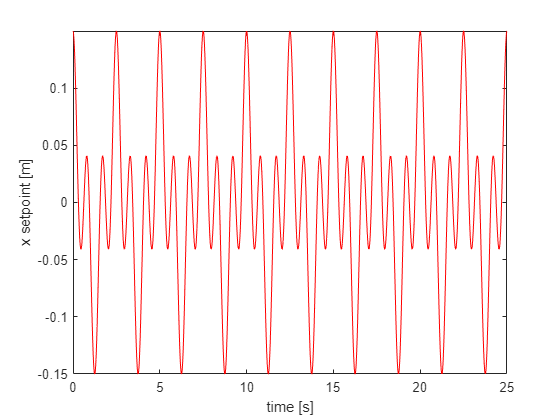

%Ideal trajectory parameters
r_sim = .15; % radius of trajectory [m] Touch screen is about 30 cm wide
% freq = 1/9; %rotations per second: 1/9 for octofolium is about as fast as it gets
% freq = 1/6; %rotations per second:  1/6 for quadrifolium is about as fast as it gets
freq = 1/2.5; %1/2.5 pushing it for n = 2, d = 5
omega_sim =  2*pi*freq; %angular frequency of circular trajectory 

%Rose curve specified by k
n = 2;
d = 1;
k = n/d;
des_traj_sym_x(VDefs.t) = r_sim*cos(k*omega_sim*VDefs.t)*cos(omega_sim*VDefs.t);
des_traj_sym_y(VDefs.t) = r_sim*cos(k*omega_sim*VDefs.t)*sin(omega_sim*VDefs.t);

figure
fplot(des_traj_sym_x, 'r') 
xlim([0 2*pi/omega_sim*10]); 
ylabel('x setpoint [m]')
xlabel('time [s]')

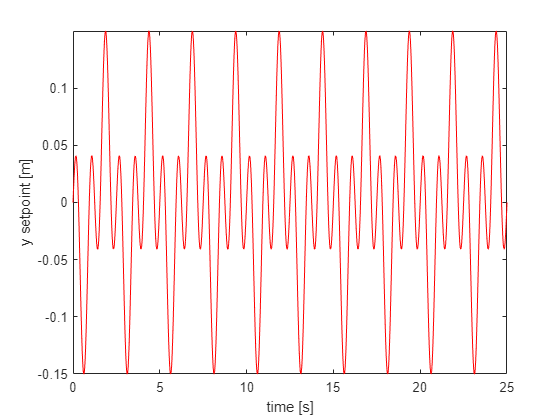


figure
fplot(des_traj_sym_y, 'r') 
xlim([0 2*pi/omega_sim*10]); 
ylabel('y setpoint [m]')
xlabel('time [s]')

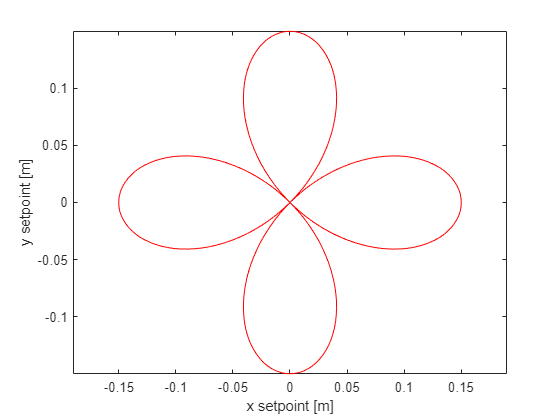


tplot = 0:0.01:100;
setpoint_shape = double([des_traj_sym_x(tplot)',des_traj_sym_y(tplot)']);
figure
plot(setpoint_shape(:,1),setpoint_shape(:,2), 'r')
xlabel('x setpoint [m]')
ylabel('y setpoint [m]')
axis equal

## Find the Linear Particular Solution and the Boundary Values

dd_x_s = diff(des_traj_sym_x,2);
syms beta_s(t) gamma_s(t) C1 C2
%Beta 
T_beta_eqn = isolate(VDefs.beta_ddot == Lnrzed_EOMs.Lin_EOMs(4), VDefs.T_beta);
T_beta_eqn = subs(T_beta_eqn,[VDefs.beta, VDefs.beta_ddot],[beta_s, diff(beta_s,2)]);    
ode_beta_s = dd_x_s == subs(Lnrzed_EOMs.Lin_EOMs(2), VDefs.T_beta, rhs(T_beta_eqn));
ode_beta_s = subs(ode_beta_s, VDefs.beta, beta_s); 
%Solve the linear ODE for beta_s(t)
beta_s_sol(VDefs.t) = dsolve(ode_beta_s);
%Take only the particular solution 
beta_s_sol = subs(beta_s_sol, [C1 C2], [0 0])

$$beta\_s\_sol(t) = -0.0624\,\cos\left(2.5133\,t\right)-0.3473\,\cos\left(7.5398\,t\right)$$

beta_s_sol_dot(VDefs.t) = diff(beta_s_sol)

$$beta\_s\_sol\_dot(t) = 0.1568\,\sin\left(2.5133\,t\right)+2.6183\,\sin\left(7.5398\,t\right)$$

BVs = double(beta_s_sol([0 2*pi/omega_sim]))

BVs =    -0.4097   -0.4097


## Produce a State Space Representation of the Nonliear ODE and Generate an EOM Function Handle 

beta_ddot_fun = matlabFunction(subs(rhs(beta_ddot_eqn), [VDefs.x_ddot, VDefs.x], [dd_x_s,des_traj_sym_x]))

beta_ddot_fun = function_handle with value:
    @(beta,beta_dot,t)sin(beta).*7.557781201848998e+1+pi.^2.*cos(t.*pi.*(4.0./5.0)).*cos(t.*pi.*(8.0./5.0)).*5.177195685670262+beta_dot.^2.*cos(t.*pi.*(4.0./5.0)).*cos(t.*pi.*(8.0./5.0)).*(7.5e+2./6.49e+2)-pi.^2.*sin(t.*pi.*(4.0./5.0)).*sin(t.*pi.*(8.0./5.0)).*4.14175654853621


beta_EOM_fun = @(t,x)[x(2)
                      beta_ddot_fun(x(1),x(2),t)]

beta_EOM_fun = function_handle with value:
    @(t,x)[x(2);beta_ddot_fun(x(1),x(2),t)]


beta_EOM_fun(0,BVs)

ans =    -0.4097
   21.1856


## Formulate the ODE as BVP and try Solving Using a BVP Solver 

Use the linear solution over the interval as an initial guess:

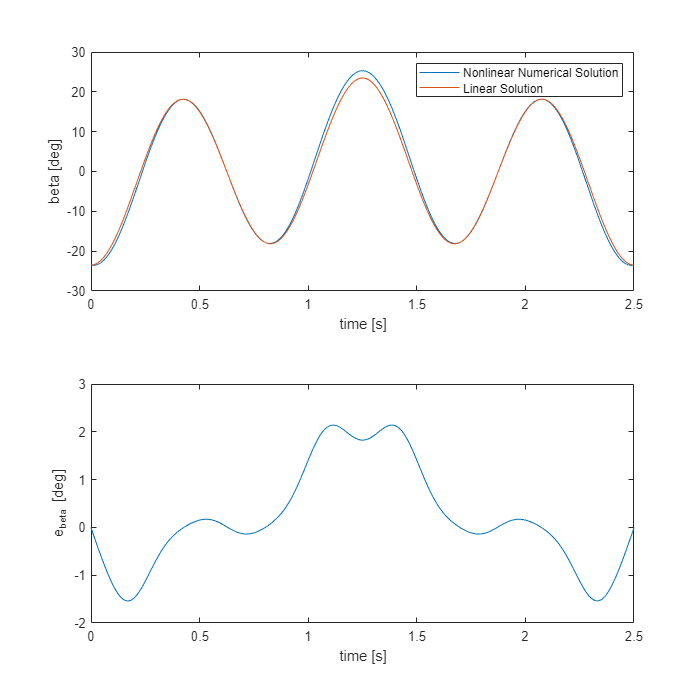

bcfcn_handle = @(ya,yb)bcfcn(ya,yb,BVs); %Residual error in the BCs function
tmesh = linspace(0,1/freq,1000); %Mesh for the initial guess
guess_fun = matlabFunction([beta_s_sol;beta_s_sol_dot]); %Initial guess at y1 and y2 (states) is beta and beta_dot from the linear solution
solinit = bvpinit(tmesh,guess_fun);
sol = bvp5c(beta_EOM_fun,bcfcn_handle,solinit);
guess_mesh = guess_fun(tmesh);

%Plot the bvp5c solution
figure
subplot(2,1,1)
plot(sol.x,rad2deg(sol.y(1,:)),tmesh,rad2deg(guess_mesh(1,:)))
xlabel('time [s]')
ylabel('beta [deg]')
legend('Nonlinear Numerical Solution','Linear Solution')
subplot(2,1,1)
subplot(2,1,2)
plot(tmesh,rad2deg(sol.y(1,:))-rad2deg(guess_mesh(1,:)))
xlabel('time [s]')
ylabel('e_{beta} [deg]')

%Make figure larger
set(gcf,'position',[0,0,700,700]);   

## Test That the BVP Solver Reproduces, Roughly, the Forcing Function

Compare the error to the error in the linear approximate solution plugged into the ODE

beta_ddot_BVP = beta_ddot_fun(sol.y(1,:),sol.y(2,:),tmesh);
% x_ddot_BVP = 

## Local Functions for the BVP Solver to Use

function res = bcfcn(ya,yb,BVs) % boundary conditions
res = [ya(1) - BVs(1)
       yb(1)-BVs(2)];
end